a.)

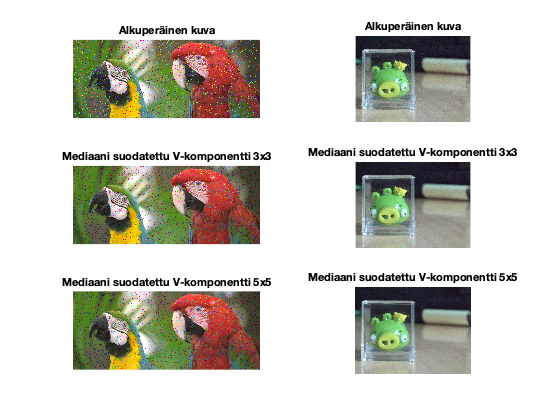

I1 = imread('rgb1.png');
I2 = imread('808test.jpg');

I1_HSV = rgb2hsv(I1);
I2_HSV = rgb2hsv(I2);
I1_HSV_V = I1_HSV(:,:,3);
I2_HSV_V = I2_HSV(:,:,3);

figure()
subplot(3, 2, 1)
imshow(I1)
title('Alkuperäinen kuva')
subplot(3, 2, 2)
imshow(I2)
title('Alkuperäinen kuva')

for i=[3 5]
    I1_V_filt = medfilt2(I1_HSV_V, [i i]);
    I1_HSV(:,:,3) = I1_V_filt;
    RGB_I1 = hsv2rgb(I1_HSV);
    subplot(3, 2, i)
    imshow(RGB_I1)
    title(sprintf('Mediaani suodatettu V-komponentti %dx%d', i, i))
    
    I2_V_filt = medfilt2(I2_HSV_V, [i i]);
    I2_HSV(:,:,3) = I2_V_filt;
    RGB_I2 = hsv2rgb(I2_HSV);
    subplot(3, 2, i+1)
    imshow(RGB_I2)
    title(sprintf('Mediaani suodatettu V-komponentti %dx%d', i, i))
end

Kohina häviää molemmista, mutta kuvasta 808test paremmin. Kuvaan rgb1 jää vielä kohinaa suodatuksen jälkeenkin, mutta se on alussakin paljon voimakkaampaa. Kohina on siis rgb1 kuvassa H ja S komponenteissa, eikä vain V-komonentissa niin kuin se on suurimmaksi osaksi 808test kuvassa.

b.)

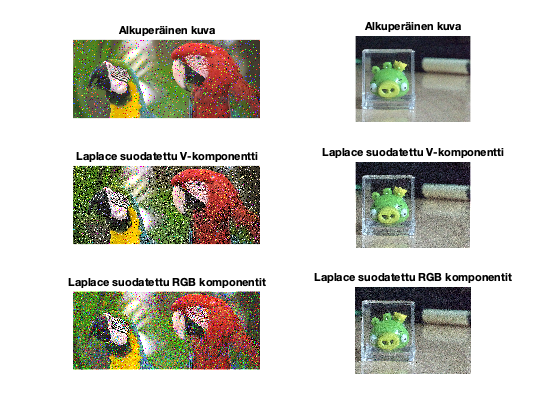

laplacian = [0,-1,0;-1,5,-1;0,-1,0];

I1_HSV = rgb2hsv(I1);
I2_HSV = rgb2hsv(I2);
I1_HSV_V = I1_HSV(:,:,3);
I2_HSV_V = I2_HSV(:,:,3);

figure()
subplot(3, 2, 1)
imshow(I1)
title('Alkuperäinen kuva')
subplot(3, 2, 2)
imshow(I2)
title('Alkuperäinen kuva')

I1_V_filt = filter2(laplacian, I1_HSV_V);
I1_HSV(:,:,3) = I1_V_filt;
RGB_I1 = hsv2rgb(I1_HSV);
subplot(3, 2, 3)
imshow(RGB_I1)
title(sprintf('Laplace suodatettu V-komponentti'))

I2_V_filt = filter2(laplacian, I2_HSV_V);
I2_HSV(:,:,3) = I2_V_filt;
RGB_I2 = hsv2rgb(I2_HSV);
subplot(3, 2, 4)
imshow(RGB_I2)
title(sprintf('Laplace suodatettu V-komponentti'))

R1 = filter2(laplacian, I1(:,:,1));
G1 = filter2(laplacian, I1(:,:,2));
B1 = filter2(laplacian, I1(:,:,3));
R2 = filter2(laplacian, I2(:,:,1));
G2 = filter2(laplacian, I2(:,:,2));
B2 = filter2(laplacian, I2(:,:,3));
I1(:,:,1) = R1;
I1(:,:,2) = G1;
I1(:,:,3) = B1;
I2(:,:,1) = R2;
I2(:,:,2) = G2;
I2(:,:,3) = B2;

subplot(3, 2, 5)
imshow(I1)
title(sprintf('Laplace suodatettu RGB komponentit'))

subplot(3, 2, 6)
imshow(I2)
title(sprintf('Laplace suodatettu RGB komponentit'))

Kohina vain lisäänty tällä tavalla

c.)

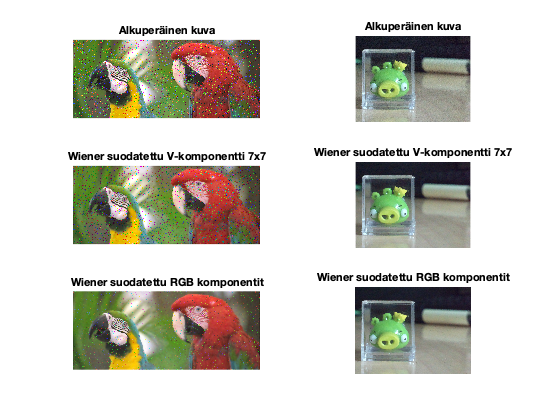

I1 = imread('rgb1.png');
I2 = imread('808test.jpg');

I1_HSV = rgb2hsv(I1);
I2_HSV = rgb2hsv(I2);
I1_HSV_V = I1_HSV(:,:,3);
I2_HSV_V = I2_HSV(:,:,3);

figure()
subplot(3, 2, 1)
imshow(I1)
title('Alkuperäinen kuva')
subplot(3, 2, 2)
imshow(I2)
title('Alkuperäinen kuva')

I1_V_filt = wiener2(I1_HSV_V, [7 7]);
I1_HSV(:,:,3) = I1_V_filt;
RGB_I1 = hsv2rgb(I1_HSV);
subplot(3, 2, 3)
imshow(RGB_I1)
title(sprintf('Wiener suodatettu V-komponentti %dx%d', 7, 7))

I2_V_filt = wiener2(I2_HSV_V, [7 7]);
I2_HSV(:,:,3) = I2_V_filt;
RGB_I2 = hsv2rgb(I2_HSV);
subplot(3, 2, 4)
imshow(RGB_I2)
title(sprintf('Wiener suodatettu V-komponentti %dx%d', 7, 7))
R1 = wiener2(I1(:,:,1), [7 7]);
G1 = wiener2(I1(:,:,2), [7 7]);
B1 = wiener2(I1(:,:,3), [7 7]);
R2 = wiener2(I2(:,:,1), [7 7]);
G2 = wiener2(I2(:,:,2), [7 7]);
B2 = wiener2(I2(:,:,3), [7 7]);

I1(:,:,1) = R1;
I1(:,:,2) = G1;
I1(:,:,3) = B1;
I2(:,:,1) = R2;
I2(:,:,2) = G2;
I2(:,:,3) = B2;

subplot(3, 2, 5)
imshow(I1)
title(sprintf('Wiener suodatettu RGB komponentit'))

subplot(3, 2, 6)
imshow(I2)
title(sprintf('Wiener suodatettu RGB komponentit'))

Kohina lähtee aika hyvin, rgb1 kuvassa hieman huonommin V-komponentilla kuin 808test kuvassa.

d.)

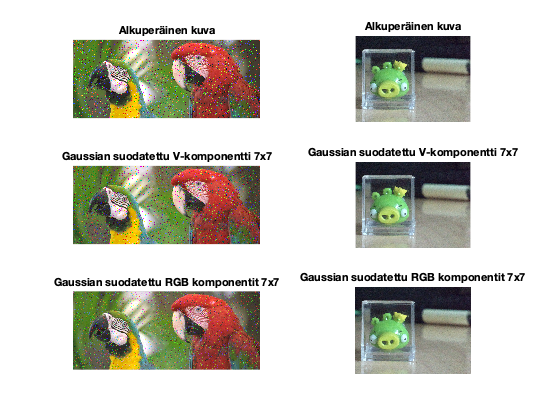

I1 = imread('rgb1.png');
I2 = imread('808test.jpg');

H = fspecial('gaussian', [7 7]);

I1_HSV = rgb2hsv(I1);
I2_HSV = rgb2hsv(I2);
I1_HSV_V = I1_HSV(:,:,3);
I2_HSV_V = I2_HSV(:,:,3);

figure()
subplot(3, 2, 1)
imshow(I1)
title('Alkuperäinen kuva')
subplot(3, 2, 2)
imshow(I2)
title('Alkuperäinen kuva')

I1_V_filt = filter2(H, I1_HSV_V);
I1_HSV(:,:,3) = I1_V_filt;
RGB_I1 = hsv2rgb(I1_HSV);
subplot(3, 2, 3)
imshow(RGB_I1)
title(sprintf('Gaussian suodatettu V-komponentti %dx%d', 7, 7))

I2_V_filt = filter2(H, I2_HSV_V);
I2_HSV(:,:,3) = I2_V_filt;
RGB_I2 = hsv2rgb(I2_HSV);
subplot(3, 2, 4)
imshow(RGB_I2)
title(sprintf('Gaussian suodatettu V-komponentti %dx%d', 7, 7))

R1 = filter2(H, I1(:,:,1));
G1 = filter2(H, I1(:,:,2));
B1 = filter2(H, I1(:,:,3));
R2 = filter2(H, I2(:,:,1));
G2 = filter2(H, I2(:,:,2));
B2 = filter2(H, I2(:,:,3));
I1(:,:,1) = R1;
I1(:,:,2) = G1;
I1(:,:,3) = B1;
I2(:,:,1) = R2;
I2(:,:,2) = G2;
I2(:,:,3) = B2;

subplot(3, 2, 5)
imshow(I1)
title(sprintf('Gaussian suodatettu RGB komponentit %dx%d', 7, 7))

subplot(3, 2, 6)
imshow(I2)
title(sprintf('Gaussian suodatettu RGB komponentit %dx%d', 7, 7))

e.)

Parhaiten kohinan poisti ja säilytti terävyyden wiener suodatin kun se tehtiin erikseen jokaiselle RGB-komponentille. Myös V-komponentin suodattimessa toimi parhaiten wienersuodatin. Mediaanisuodin oli toiseksi paras. Huonoin oli Laplace suodatin, mutta en ole varma sainko sen tehtyä oikein.